# noise

clear;
Fs = 44100;
T = 1 / Fs;
L = Fs * 1;
% X = zeros(L, 1);
t = (0:L-1)*T;
% size(X)
% mags = zeros(1, L/2+1) + 1;
% mags = randn(1, L/2+1);
mags = linspace(0, 1, L/2 + 1);

% mags = mags - 1/22050 * 440*4;
% mags = exp(-200*mags.*mags);

% mags = exp(-2*mags) .* sin(22*mags).^222;
mags = exp(-2*mags) .* sin(10*mags).^222;

% mags = exp(-200*mags);
% mags(1:end) = 1;
mags = mags - min(mags)

mags =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% mags(2000:end) = 187;
% phases = zeros(1, L/2+1);
% phases = randn(1, L/2+1);
% phases = rand(1, L/2+1);
% phases = mod(randn(1, L/2+1), 1);
phases = linspace(pi, -pi, L/2 + 1);
phases = 0*phases + 1*rand(1, L/2+1) + 0.0*sin(phases*2000000/pi + 0.5);
% phases = tan(phases*20200);
phases = phases - min(phases);
phases = phases / max(phases);
phases = (phases - 0.5) * 2;
phases = phases * pi;

f = Fs/L*(0:(L/2));
plot(f(1:end/10),mags(1:end/10)) 

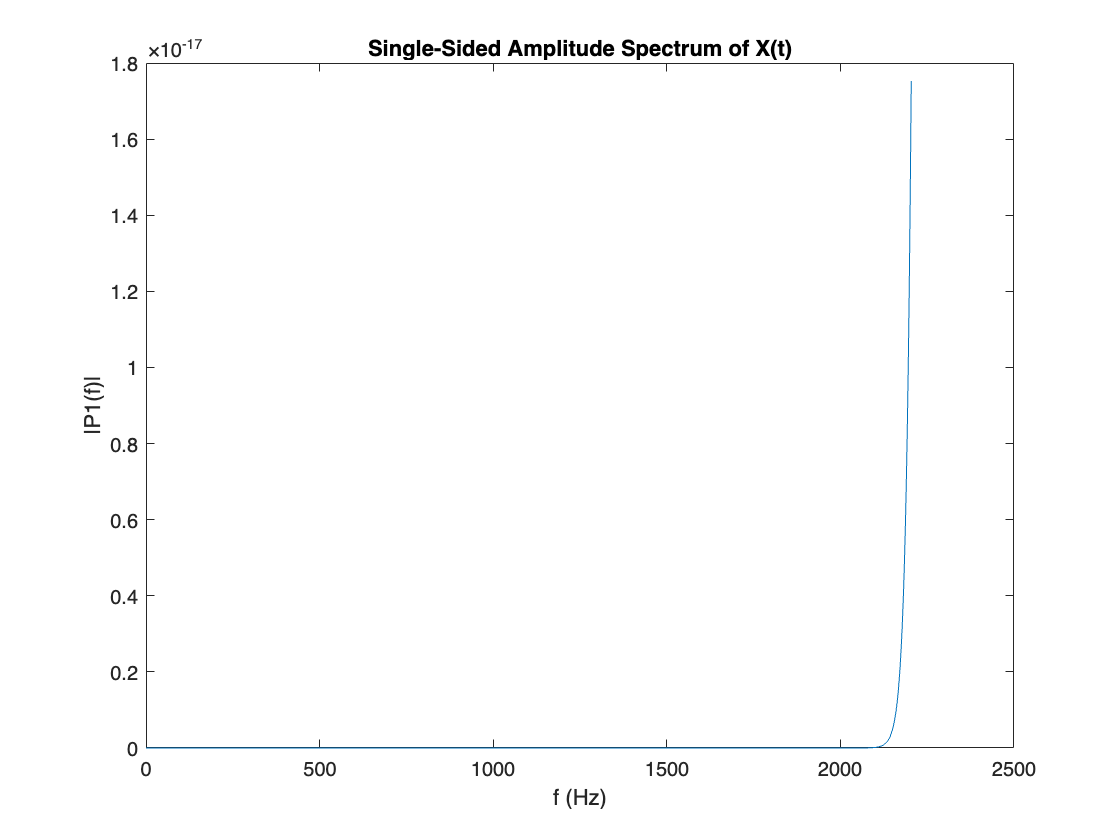

title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

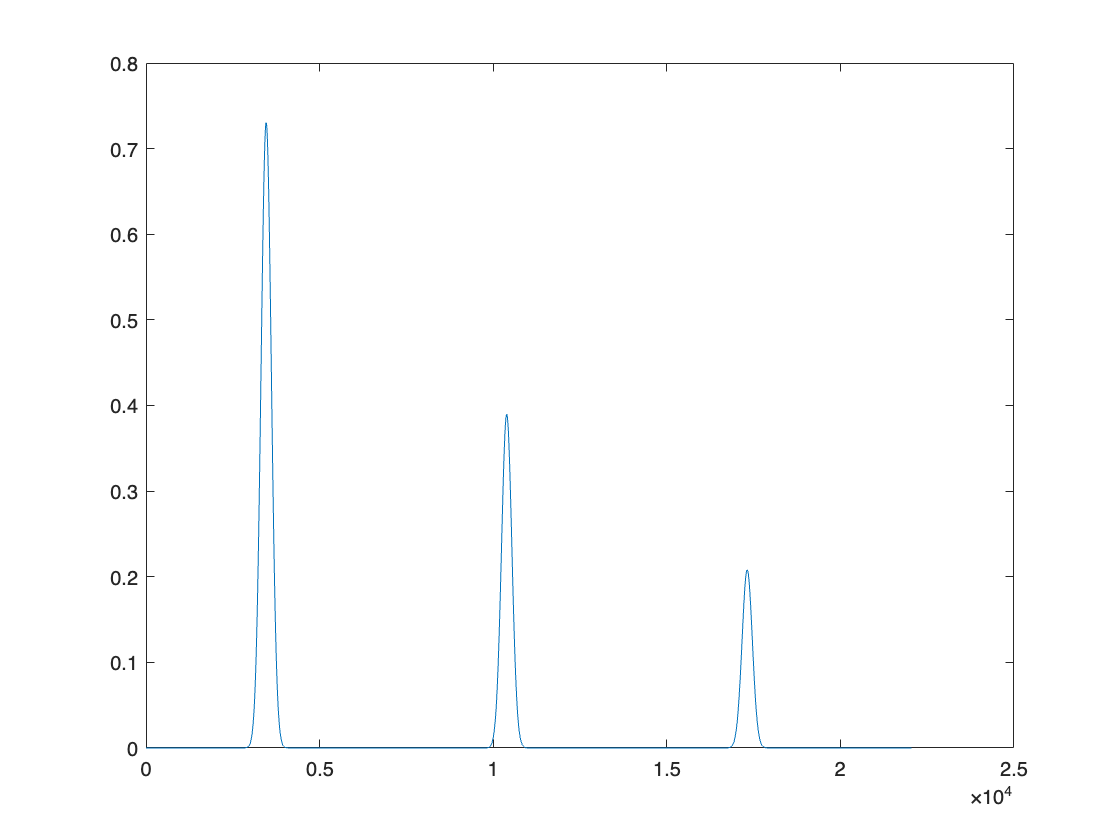

plot(f,mags)

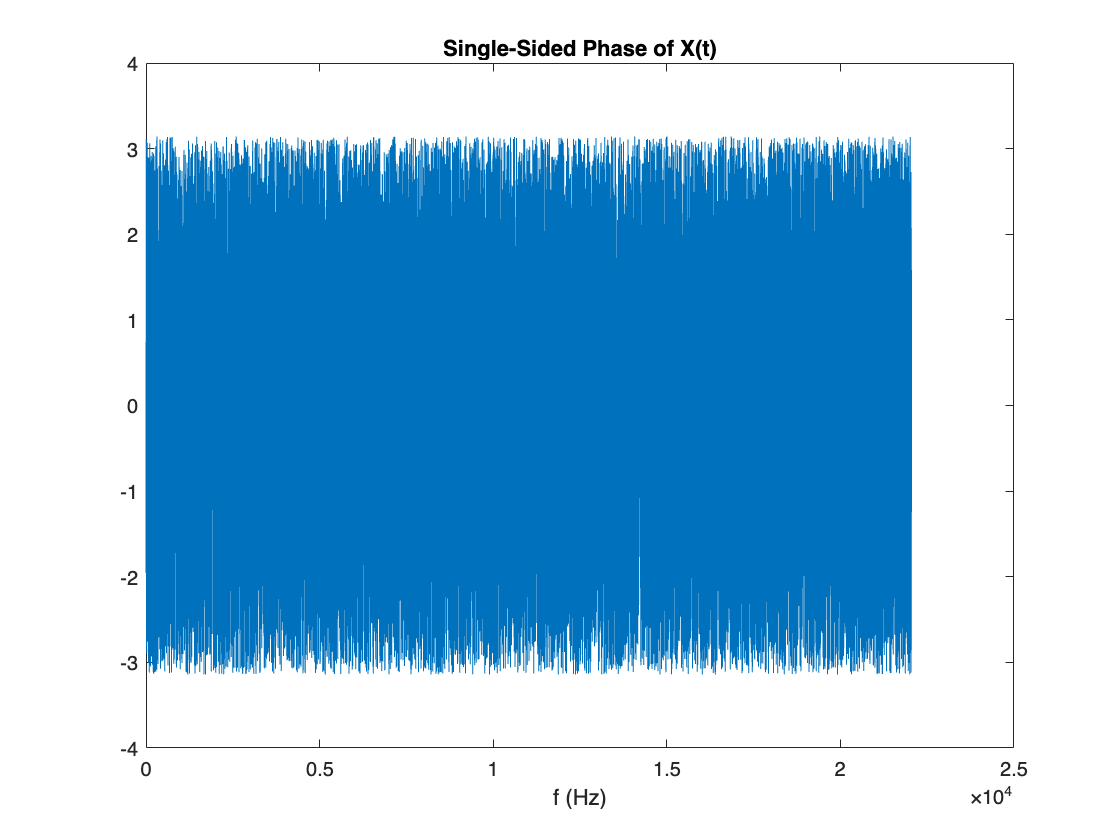


f = Fs/L*(0:(L/2));
plot(f,phases) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")

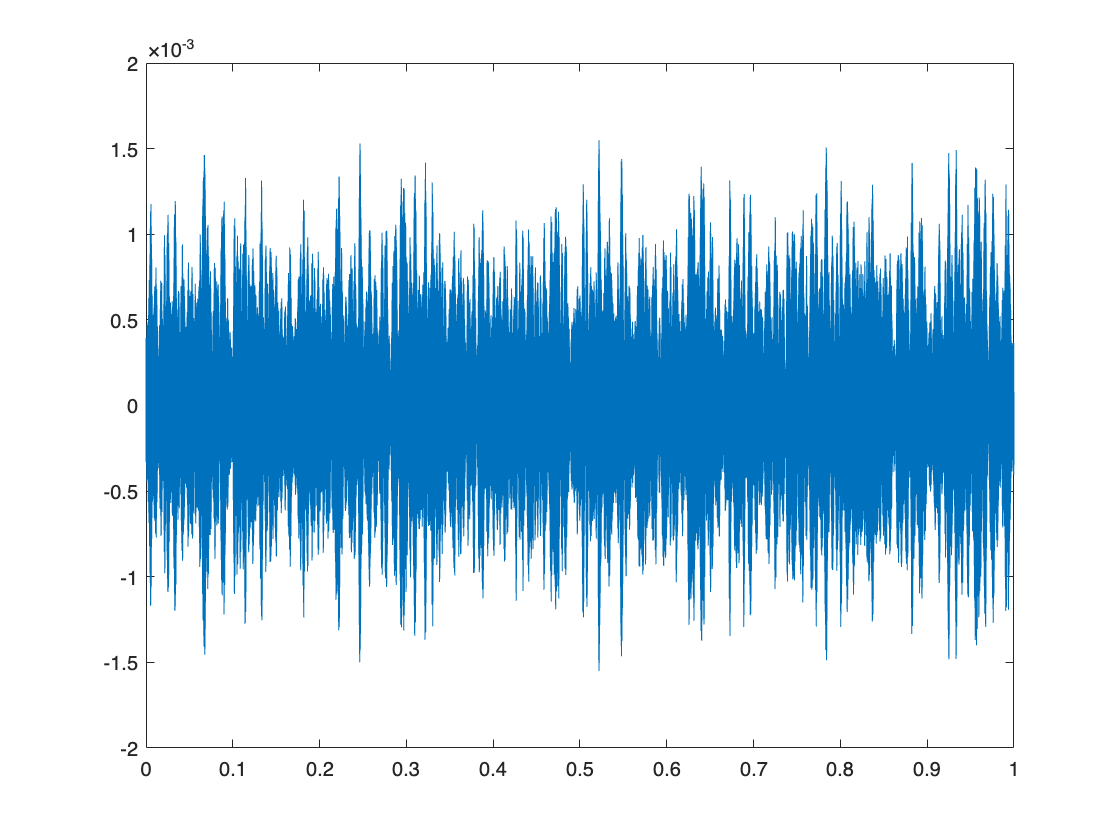


recs = zeros(1, L);
for i = 0:(L/2)
    mag = mags(i+1);
    phase = phases(i+1);
    add = 2*mag/L * cos(2*pi*t*Fs/L*i + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(t,recs);

recs(1)

ans = 3.9433e-04

recs(end)

ans = 7.7701e-05

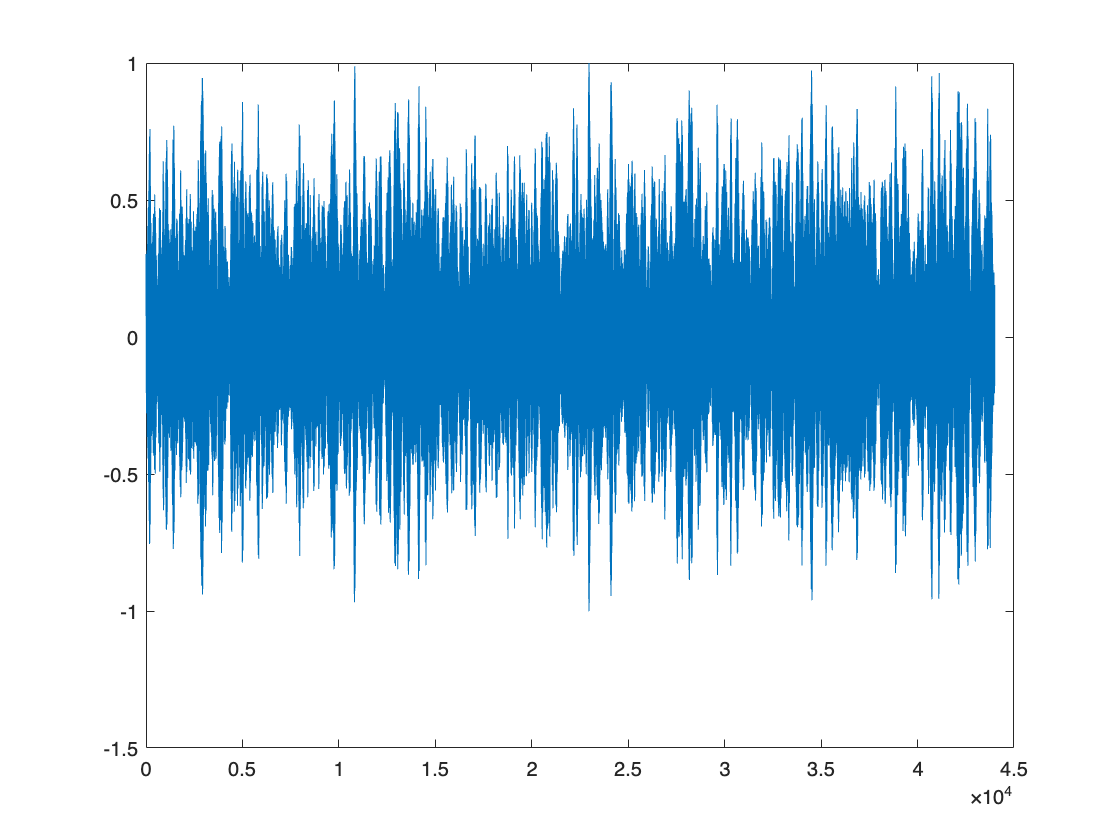

smoothening = 50;

recs = recs(1+smoothening:end-smoothening);
recs = recs / max(recs);
plot((1:L - 2*smoothening),recs);


prepend = linspace(0, recs(1), smoothening)

prepend =          0    0.0016    0.0032    0.0048    0.0064    0.0080    0.0096    0.0112    0.0128    0.0144    0.0160    0.0176    0.0192    0.0208    0.0224    0.0240    0.0256    0.0272    0.0288    0.0304    0.0320    0.0337    0.0353    0.0369    0.0385    0.0401    0.0417    0.0433    0.0449    0.0465    0.0481    0.0497    0.0513    0.0529    0.0545    0.0561    0.0577    0.0593    0.0609    0.0625    0.0641    0.0657    0.0673    0.0689    0.0705    0.0721    0.0737    0.0753    0.0769    0.0785


append = linspace(recs(end), 0, smoothening)

append =     0.1896    0.1858    0.1819    0.1780    0.1741    0.1703    0.1664    0.1625    0.1587    0.1548    0.1509    0.1471    0.1432    0.1393    0.1354    0.1316    0.1277    0.1238    0.1200    0.1161    0.1122    0.1084    0.1045    0.1006    0.0967    0.0929    0.0890    0.0851    0.0813    0.0774    0.0735    0.0697    0.0658    0.0619    0.0580    0.0542    0.0503    0.0464    0.0426    0.0387    0.0348    0.0310    0.0271    0.0232    0.0193    0.0155    0.0116    0.0077    0.0039         0


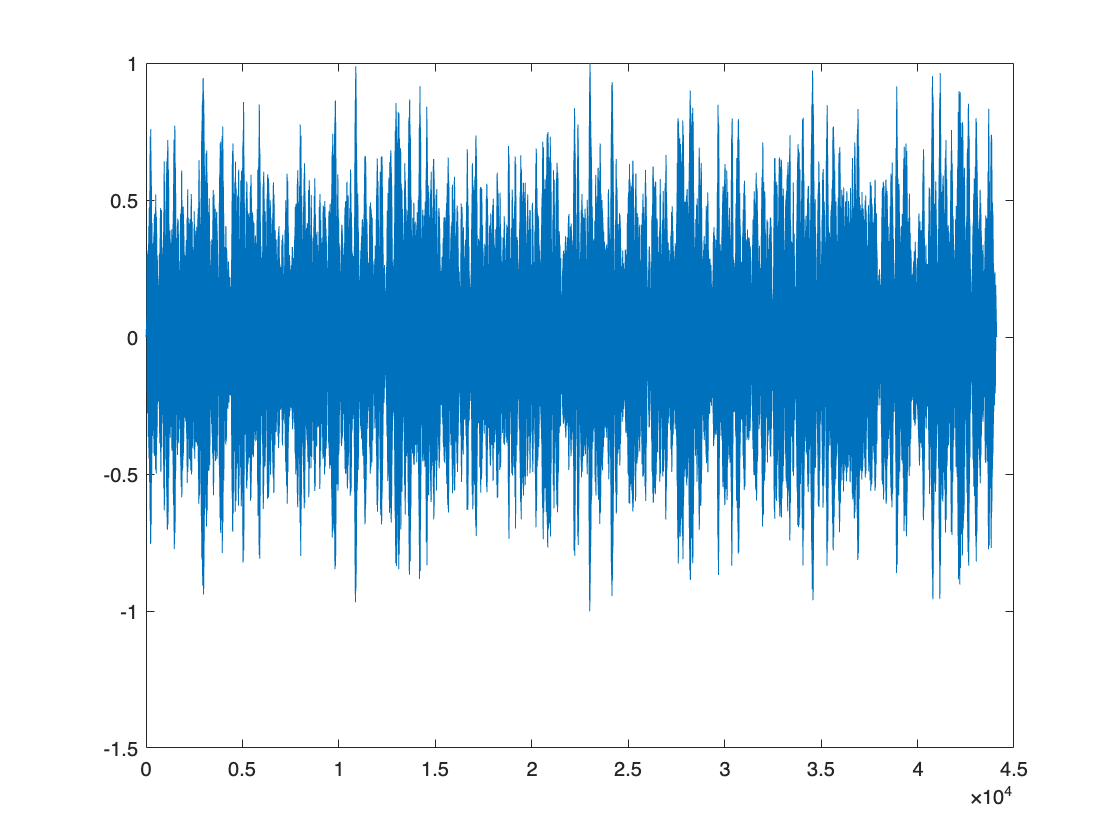

recs = [prepend recs append];
plot((1:L),recs);

recs(1)

ans = 0

recs(end)

ans = 0

min(recs)

ans = -1.0013

max(recs)

ans = 1

audiowrite("recr.wav",recs,Fs)